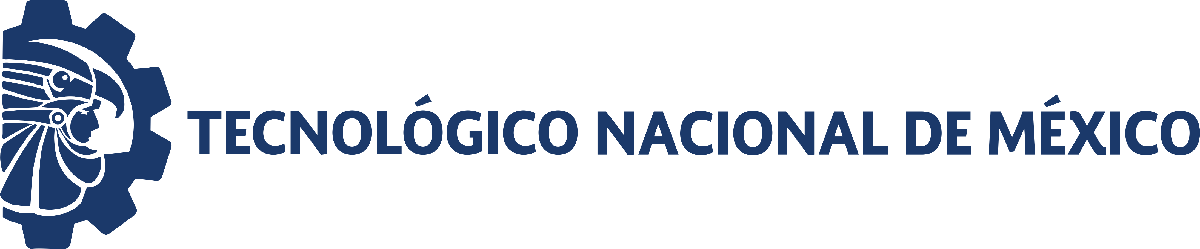                                 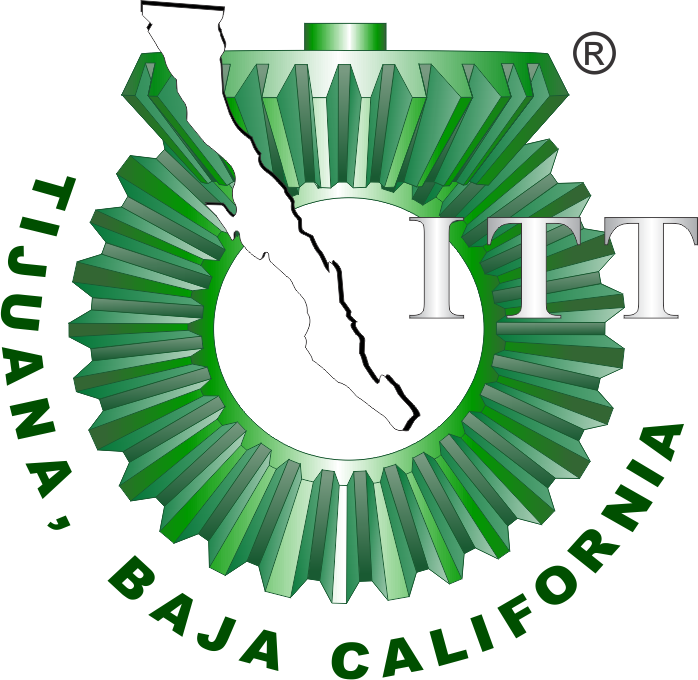

# Práctica Tres: Sistema Musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

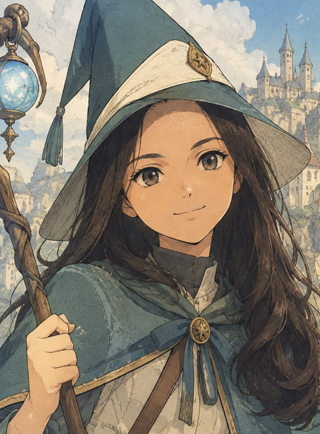

Nombre del alumno: **Gabriela Gissele Alvarez Garcia**

Número de control: **C22211520**

Correo institucional: **C22211520@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system("SistemaP3")
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('SistemaP3', parameters);


## Respuesta Control, Caso y Tratamiento

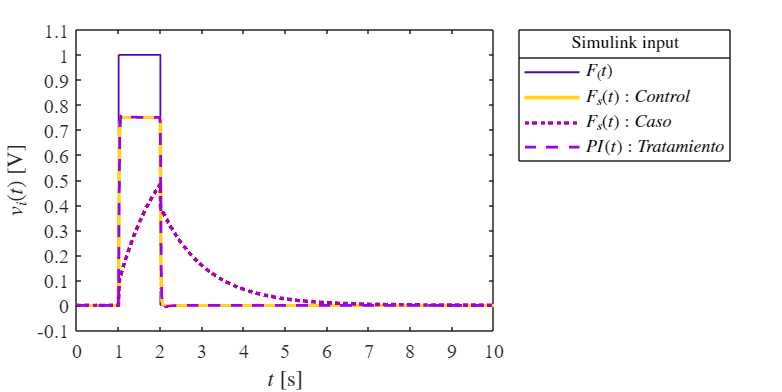


plotsignals(x.t,x.F,x.Fsx,x.Fsy,x.PID,'Simulink');

## **Modelo de Ecuaciones Integro-Diferenciales**

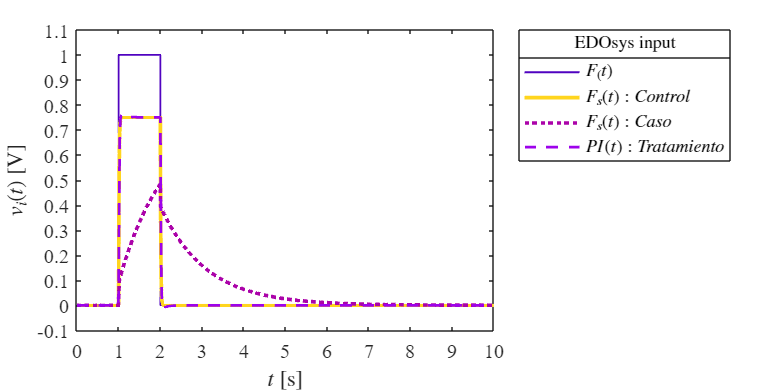

dt= 1e-3;
t= (0:dt:10)';
F= zeros(length(t),1); F(1/dt:2/dt)=1;
PID= interp1(x.t,x.PID,t,"previous");

par_control= [0.25,10e-6,100e-6,100];
par_caso= [0.25,10e-6,100e-6,10e3];

Fs_control = musculoesqueletico(par_control,F,t);
Fs_caso = musculoesqueletico(par_caso,F,t);

plotsignals(t,F,Fs_control,Fs_caso,PID,'EDOsys');

function Fs= musculoesqueletico(par,F,t)
    alpha = par(1); Cs=par(2); Cp = par(3); R= par(4); dt= t(2);
    n= round(t(end)/dt);
    x= zeros(length(t),1); x(1)=0;
    Fs = zeros(length(t),1); Fs(1)=0;
    for i = 1:n
        x(i+1)=x(i)+((F(i)-x(i))/(R*(Cp+Cs)))*dt;%EDO
        Fs(i+1) = Cs*F(i)/(Cp+Cs) + (1-alpha-Cs/(Cp+Cs))*x(i);%funcion
    end
end



## **Función: Respuestas de la simulación**

function plotsignals(t,F,Fsx,Fsy,PID,signal)
set(figure(), "color", 'w')
set(gcf, 'units', 'inches','position',[1,1,7,3.5])
set(gca, 'fontname', 'times new roman', 'fontsize', 11)
hold on; grid off, box on;
clr1 = [80,3,192]/255;
clr3 = [171,3,169]/255; %amarillo
clr2 = [255,213,30]/255;
clr4 = [157, 2, 235]/255;%morado
order = [clr1;clr2;clr3;clr4]; colororder(order)

plot(t,F,'-','LineWidth',1.0,'color',clr1) %entrada
plot(t,Fsx,'-','LineWidth',2.0,'color',clr2) %control
plot(t,Fsy,':','LineWidth',2.0,'color',clr3) %caso
plot(t,PID,'--','LineWidth',1.5,'color',clr4) %PID
L = legend('$F_(t)$','$F_{s}(t): Control$','$F_s(t): Caso$','$PI(t): Tratamiento$');

set(L,'interpreter','latex','location','northeastoutside','orientation','vertical')
title(L,[signal,' input'])
xlabel('$t$ [s]','interpreter','latex')
ylabel('$v_i(t)$ [V]','Interpreter','latex')
xlim([0 10]); xticks(0:1:10)
ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')
end
